clc;
clear;
close all;
% to clear all windows and close all images

n1 = [0 3.3928 -340.09 39451];
d1 = [1 74.38 5589 42107];

sys1 = tf(n1,d1)

sys1 =
 
    3.393 s^2 - 340.1 s + 39451
  --------------------------------
  s^3 + 74.38 s^2 + 5589 s + 42107
 
Continuous-time transfer function.
Model Properties


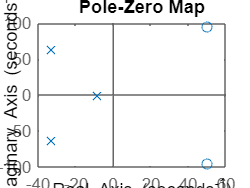

figure;
grid on
pzmap(sys1)

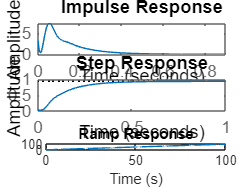

%Impulse response
figure;
subplot(311)
impulse(sys1);
title('Impulse Response');

%Step response
subplot(312)
step(sys1);
title('Step Response');

%Ramp Response
t = 0:0.01:100;
ramp = t;
[y, t] = lsim(sys1, ramp, t);
subplot(313)
plot(t, y);
title('Ramp Response');
xlabel ('Time (s)'); ylabel('Output');